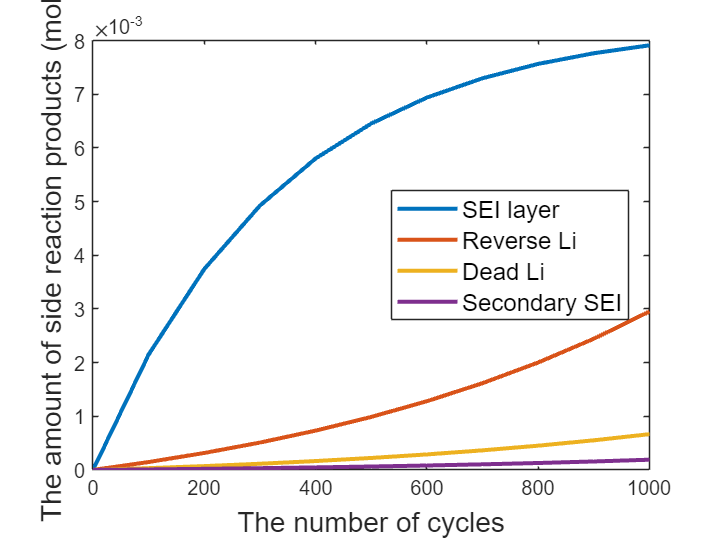

clear;
clc;

load L_sei.mat;
load L_li.mat;

M_sei=0.16;     %kg/mol;    ren_M_sei=0.162;
rho_sei=1.6e3;  %kg/m^3;    ren_rho_sei=1.69e3;

M_li=6.94*10^-3;    %[kg/mol]
rho_li=534;         %[kg/m^3]

Lneg=100e-6;

cycle_no=(0:10)*100;
ratio=[0.775,0.175,0.05];
ratio_li=L_li(:,2)*ratio;
aging_matrix=[L_sei,ratio_li];

aging_mol=aging_matrix(:,1);

epssneg=0.471;
Rsn=12.5e-6;
Av=3*epssneg/Rsn;

mol=aging_matrix(:,2:end)*Av*rho_sei/M_sei*Lneg;

aging_mol=[aging_mol,mol];

kappa_film=5e-6;

figure(1);
clf;
plot(aging_mol(:,1),aging_mol(:,2:end),'LineWidth',2);
xlabel('The number of cycles',"FontSize",14);
ylabel('The amount of side reaction products (mol)','FontSize',14);
legend('SEI layer','Reverse Li','Dead Li','Secondary SEI','Location',"best",'FontSize',12);

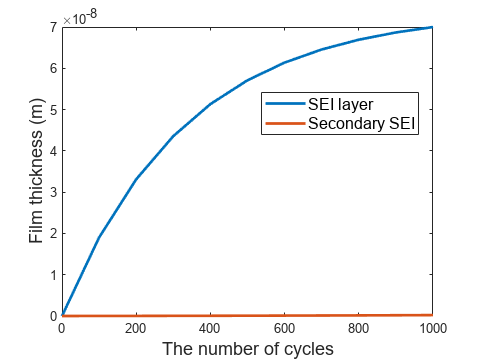

d_film=aging_matrix(:,1:2);
d_film=[d_film,aging_mol(:,end)/Lneg*M_li/Av/rho_li];
figure(2);
clf;
plot(d_film(:,1),d_film(:,2:end),'LineWidth',2);
xlabel('The number of cycles',"FontSize",14);
ylabel('Film thickness (m)','FontSize',14);
legend('SEI layer','Secondary SEI','Location',"best",'FontSize',12);

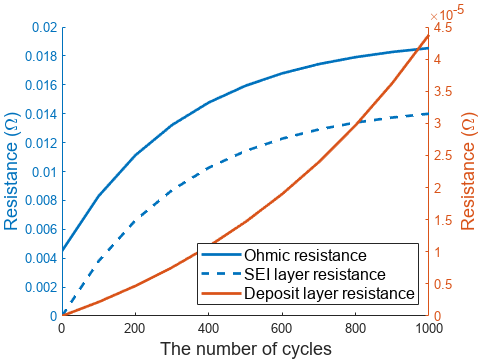

R_film=d_film(:,1);
R_aging=d_film(:,2:3)/kappa_film;
R_film=[R_film,4.5e-3+sum(R_aging,2),R_aging];
figure(3);
clf;
yyaxis left;
hold on;
plot(R_film(:,1),R_film(:,2),'LineWidth',2);
plot(R_film(:,1),R_film(:,3),'LineWidth',2);
xlabel('The number of cycles',"FontSize",14);
ylabel('Resistance (\Omega)','FontSize',14);
yyaxis right;
h1=plot(R_film(:,1),R_film(:,4),'LineWidth',2);
ylabel('Resistance (\Omega)','FontSize',14);
legend('Ohmic resistance','SEI layer resistance','Deposit layer resistance','Location',"southeast",'FontSize',12);

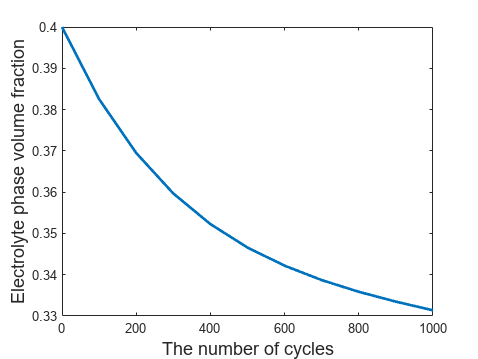

Lpos=183e-6;
Lsep=52e-6;
Lsum=Lpos+Lneg+Lsep;
electrolyte_li=Lneg*1000;
aging_electrolyte=2*(aging_mol(:,2)+aging_mol(:,4));
rate_electrolyte=(electrolyte_li-aging_electrolyte)/electrolyte_li;
aging_epsl=0.4*rate_electrolyte;
figure(4);
clf;
plot(aging_matrix(:,1),aging_epsl,'LineWidth',2);
xlabel('The number of cycles',"FontSize",14);
ylabel('Electrolyte phase volume fraction','FontSize',14);

# 液相扩散简化

cl=1000;
T=298.3;
De=10^(-8.43-54/(T-229-0.005*cl)-cl*2.2e-4);
De2=7.5e-11;
epsl=0.4;
Xequ=(-2*Lneg^2+3*Lsep^2+2*Lpos^2+6*Lsep*Lpos)/6/Lsum;
P=-epsl*(Lneg^2/3+Lneg*Xequ+Xequ^2/2);
Q1=-2/(Lneg+2*Xequ);
Q2=-2/(Lpos+2*(Lsep-Xequ));
t_plus=0.363;
Rg=8.314;
I=ones(3700,1)*17.5;
F=96485.33;
Aera=1;

matrix_cen=[];
matrix_cep=[];

tic;
for epsl=aging_epsl'
dcen(1)=0;
dcep(1)=0;

for i=1:length(I)
    ddcen=De*epsl^1.5*dcen(i)/P-(1-t_plus)*I(i)/F/Aera/P/Q1;
    dcen(i+1)=dcen(i)+ddcen;
    ddcep=De*epsl^1.5*dcep(i)/P+(1-t_plus)*I(i)/F/Aera/P/Q2;
    dcep(i+1)=dcep(i)+ddcep;
end
cen=dcen+1000;
cen=cen';
cep=dcep+1000;
cep=cep';

matrix_cep=[matrix_cep,cep];
matrix_cen=[matrix_cen,cen];
end
toc;

历时 0.025448 秒。


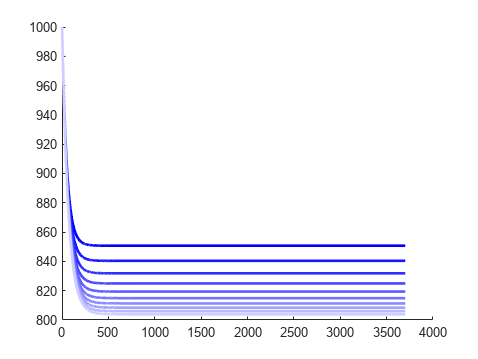

for i=1:11
    V_ce(:,i)=(1+t_plus)*2*Rg*T/F*log(matrix_cep(2:end,i)./matrix_cen(2:end,i));
end


figure(5);
clf;
r=linspace(0,0.9,11);
g=linspace(0,0.9,11);
b=linspace(0,0.9,11);
hold on;
for i=1:10
    plot(matrix_cen(:,i),'LineWidth',2,'Color',[r(i),g(i),1]);
end

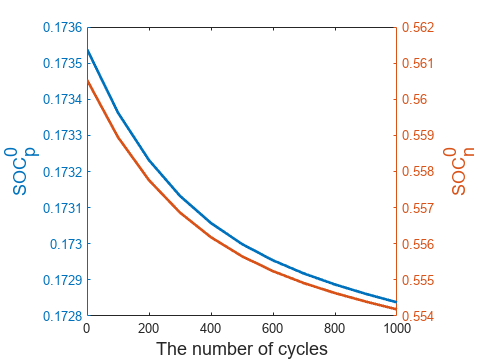

Rsp=8e-6;
Rsn=12.5e-6;

epsspos=0.297;
epssneg=0.471;

F=96485.33289;
Aera=1;

cs0pos=3900;
cs0neg=14870;

csmaxpos=22860;
csmaxneg=26390;

soc0pos=cs0pos/csmaxpos;
soc0neg=cs0neg/csmaxneg;

Qp=Lpos*epsspos*Aera*csmaxpos*F/3600;
Qn=Lneg*epssneg*Aera*csmaxneg*F/3600;

li_pos_init=Lpos*epsspos*cs0pos;
li_neg_init=Lneg*epssneg*cs0neg;

total_li=li_neg_init+li_pos_init;

loss_li=aging_mol(:,2)+aging_mol(:,4)+aging_mol(:,5);

remain_li=total_li-loss_li;

ocv=Eeq_pos(soc0pos)-Eeq_neg(soc0neg);

for k=1:11
[soc0pos_matrix(k),soc0neg_matrix(k)]=init_soc(4.2,k);
end

figure(6);
clf;
yyaxis left;
plot(aging_matrix(:,1),soc0pos_matrix,'LineWidth',2);
% xlabel('The number of cycles',"FontSize",14);
ylabel('SOC_p^0','FontSize',14);
yyaxis right;
plot(aging_matrix(:,1),soc0neg_matrix,'LineWidth',2);
xlabel('The number of cycles',"FontSize",14);
ylabel('SOC_n^0','FontSize',14);

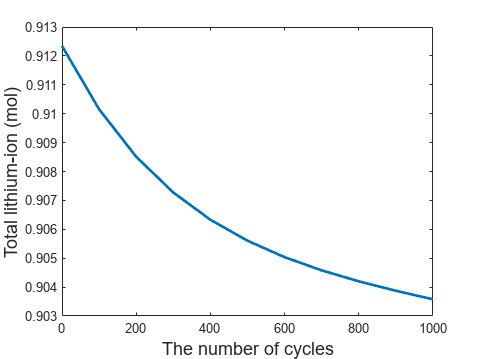

figure(11);
clf;
plot(aging_matrix(:,1),remain_li,'LineWidth',2);
xlabel('The number of cycles',"FontSize",14);
ylabel('Total lithium-ion (mol)','FontSize',14);

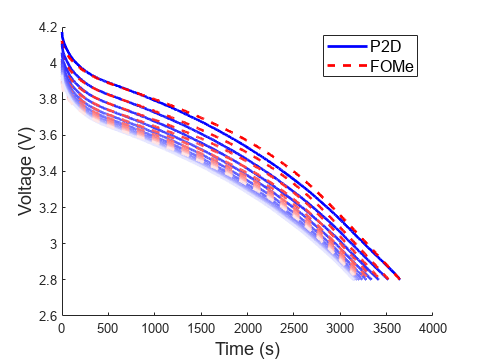


load p2d_V.txt;
load p2d_socsurfp.txt;
load p2d_socsurfn.txt;
load p2d_capacity.txt;
index=mod(p2d_V(:,1),1)==0;
p2d_V=p2d_V(index,:);
p2d_socsurfp=p2d_socsurfp(index,:);
p2d_socsurfn=p2d_socsurfn(index,:);
p2d_capacity=p2d_capacity(index,:);

p2d_matrix=[p2d_socsurfp,p2d_socsurfn(:,2),p2d_V(:,2)];
index=p2d_matrix(:,1)==1;
t=1:length(index);
t=t';
index_cycle=t(index);

R_sim=R_film(:,2);
figure(8);
clf;
hold on;
for i=1:10
   Vp2d=p2d_matrix(index_cycle(i):index_cycle(i+1)-1,4);
   plot(Vp2d,'LineWidth',2,'Color',[r(i),g(i),1]) ;
   V_index=1:length(Vp2d);
   V=Eeq_pos(p2d_matrix(index_cycle(i):index_cycle(i+1)-1,2))...
       -Eeq_neg(p2d_matrix(index_cycle(i):index_cycle(i+1)-1,3))-17*R_sim(i)+V_ce(V_index,i); %R_film(:,2)
   plot(V,'LineWidth',2,'Color',[1,g(i),b(i)],'LineStyle',"--") ;
   RMSE(i)=sqrt(mean((Vp2d-V).^2));
   MAPE(i)=mean(abs((Vp2d-V)./Vp2d))*100;
   MAX(i)=max(abs(Vp2d-V));
   Time(i)=length(V);
end
Vp2d=p2d_matrix(index_cycle(11):end,4);
plot(Vp2d,'LineWidth',2,'Color',[r(11),g(11),1]);
V_index=1:length(Vp2d);
V=Eeq_pos(p2d_matrix(index_cycle(11):end,2))...
       -Eeq_neg(p2d_matrix(index_cycle(11):end,3))-17*R_sim(11)+V_ce(V_index,11); %R_film(:,2)
plot(V,'LineWidth',2,'Color',[1,g(11),b(11)],'LineStyle',"--") ;
xlabel('Time (s)',"FontSize",14);
ylabel('Voltage (V)','FontSize',14);
legend('P2D','FOMe','Location',"best",'FontSize',12);

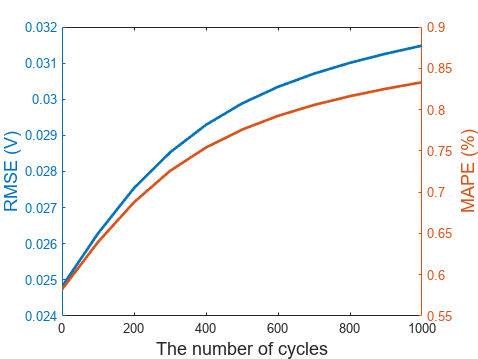

RMSE(11)=sqrt(mean((Vp2d-V).^2));
MAPE(11)=mean(abs((Vp2d-V)./Vp2d))*100;
MAX(11)=max(abs(Vp2d-V));
Time(11)=length(V);

figure(9);
clf;
yyaxis left;
plot(cycle_no,RMSE,'LineWidth',2);
xlabel('The number of cycles',"FontSize",14);
ylabel('RMSE (V)','FontSize',14);
yyaxis right;
plot(cycle_no,MAPE,'LineWidth',2);
ylabel('MAPE (%)','FontSize',14);

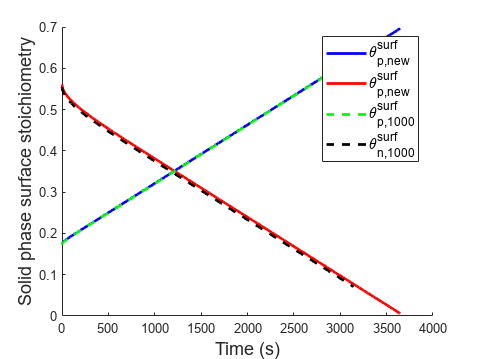


socsurfp0=p2d_matrix(index_cycle(1):index_cycle(2)-1,2);
socsurfn0=p2d_matrix(index_cycle(1):index_cycle(2)-1,3);

socsurfp1000=p2d_matrix(index_cycle(11):end,2);
socsurfn1000=p2d_matrix(index_cycle(11):end,3);

figure(10);
clf;
hold on;
plot(socsurfp0,'Color','b','LineWidth',2);
plot(socsurfn0,'Color','r','LineWidth',2);
plot(socsurfp1000,'Color','g','LineWidth',2,"LineStyle","--");
plot(socsurfn1000,'Color','k','LineWidth',2,"LineStyle","--");
legend('\theta^{surf}_{p,new}','\theta^{surf}_{p,new}','\theta^{surf}_{p,1000}','\theta^{surf}_{n,1000}','Location',"best",'FontSize',12);
xlabel('Time (s)',"FontSize",14);
ylabel('Solid phase surface stoichiometry',"FontSize",14);

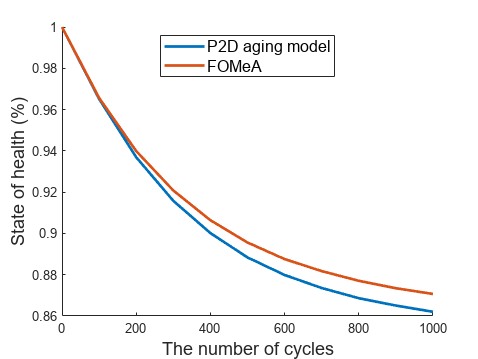

% index_Q=[index_cycle(2:end)-1;36299];
% p2dQ=p2d_capacity(index_Q,1);
% p2d_soh=p2dQ/p2dQ(1);
p2dQ=[index_cycle;36299];
p2dQ=diff(p2dQ);
p2d_soh=p2dQ/p2dQ(1);

% i=10;
% 
% V=Eeq_pos(p2d_matrix(index_cycle(i):index_cycle(i+1)-1,2))...
%        -Eeq_neg(p2d_matrix(index_cycle(i):index_cycle(i+1)-1,3))-17*R_sim(i); %R_film(:,2)
kq=1:length(V);

FOMq=[3611,3487,3394,3325,3273,3234,3205,3184,3167,3154,3144];

FOMeA_soh=FOMq/3600*17;
FOMeA_soh=FOMeA_soh/FOMeA_soh(1);

figure(12);
clf;
hold on;
plot(aging_matrix(:,1),p2d_soh,'linewidth',2);
plot(aging_matrix(:,1),FOMeA_soh,'LineWidth',2);
legend('P2D aging model','FOMeA','Location',"best",'FontSize',12);
xlabel('The number of cycles',"FontSize",14);
ylabel('State of health (%)','FontSize',14);

RMSE=sqrt(mean((p2d_soh-FOMeA_soh').^2))

RMSE =     0.0065175


MAPE=mean(abs((p2d_soh-FOMeA_soh')./p2d_soh))*100

MAPE =       0.65219


MAX=max(abs(p2d_soh-FOMeA_soh'))

MAX =     0.0086324



% tic;
% Dsp=1e-13;
% Dsn=3.9e-14;
% 
% Qp=Lpos*epsspos*csmaxpos*F/3600;
% Qn=Lneg*epssneg*csmaxneg*F/3600;
% 
% I=-ones(3646,1)*17;
% [dsocp,dsocn]=fom(Rsp,Rsn,Dsp,Dsn,I,Qp,Qn);
% soc0p=soc0pos_matrix(1);
% soc0n=soc0neg_matrix(1);
% socp=soc0p-cumsum(I/3600/Qp);
% socn=soc0n+cumsum(I/3600/Qn);
% 
% socsurfp=socp-dsocp;
% socsurfn=socn+dsocn;
% 
% V=Eeq_pos(socsurfp)-Eeq_neg(socsurfn)+6e-3*17;
% 
% toc;